# Projeto 1

clear all;
close all; 
clc; 



## Analise

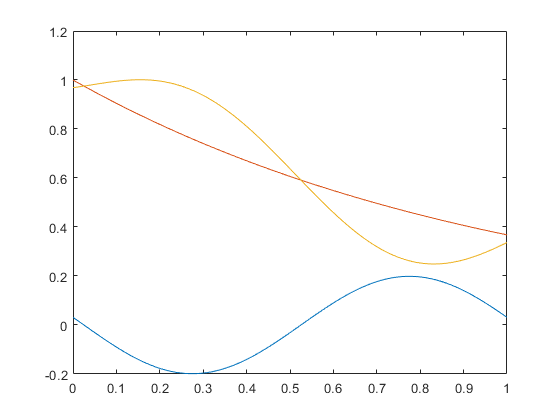

syms t tempo

To = 1;
wo = 2*pi/To;

gt = exp(-t);
g = @(t) exp(-t);
gn = @(n) exp(-(j)*n*wo*t);
c1 = int(gt*gn(1),t,0,To)/To;
c_1 = int(gt*gn(-1),t,0,To)/To;
p1 = @(tempo) c1*exp(-j*wo*tempo) + c_1*exp(j*wo*tempo);


tempo = [0:0.01:To];
r1 = g(tempo) - p1(tempo);
figure(1)
xlabel('Tempo')
plot(tempo, p1(tempo),tempo,g(tempo),tempo,r1)

c2 = int(gt*gn(2),t,0,To)/To

$$c2 = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{4\,\pi -\mathrm{i}}$$

c_2 = int(gt*gn(-2),t,0,To)/To

$$c\_2 = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+4\,\pi \,\mathrm{i}}$$

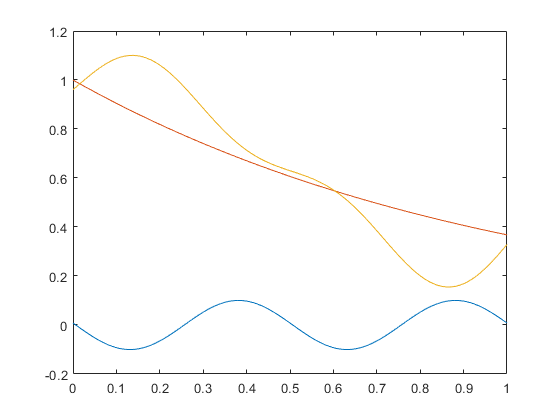

p2 = @(tempo) c2*exp(-2*j*wo*tempo) + c_2*exp(2*j*wo*tempo);
r2 = g(tempo) - (p1(tempo)+p2(tempo));
figure(2)
xlabel('Tempo')
plot(tempo, p2(tempo),tempo,g(tempo),tempo,r2)

p1c = c1*exp(-j*wo*t) + c_1*exp(j*wo*t);
r1c = gt - p1c;
c2r = int(r1c*gn(2),t,0,To)/To

$$c2r = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)\,\mathrm{i}}{4\,\pi -\mathrm{i}}$$

c_2r = int(r1c*gn(-2),t,0,To)/To

$$c\_2r = -\frac{{\mathrm{e}}^{-1}\,\left(\mathrm{e}-1\right)}{-1+4\,\pi \,\mathrm{i}}$$

%%% Conclui que trocando a função gt que é o sinal pelo residuo, se chega no
%%% mesmo valor para os coeficientes, Pois ao utilizar o valor para N = 2
%%% acaba tendo uma função de residuo muito proxima a gt

cn = int(gt*gn,t,0,To)/To;
N = 1000;
n = [-N:1:N];
c = eval(cn)

c =    0.0000 + 0.1006i   0.0000 + 0.1007i   0.0000 + 0.1008i   0.0000 + 0.1009i   0.0000 + 0.1010i   0.0000 + 0.1011i   0.0000 + 0.1012i   0.0000 + 0.1013i   0.0000 + 0.1014i   0.0000 + 0.1015i   0.0000 + 0.1016i   0.0000 + 0.1017i   0.0000 + 0.1018i   0.0000 + 0.1019i   0.0000 + 0.1020i   0.0000 + 0.1021i   0.0000 + 0.1022i   0.0000 + 0.1023i   0.0000 + 0.1024i   0.0000 + 0.1026i   0.0000 + 0.1027i   0.0000 + 0.1028i   0.0000 + 0.1029i   0.0000 + 0.1030i   0.0000 + 0.1031i   0.0000 + 0.1032i   0.0000 + 0.1033i   0.0000 + 0.1034i   0.0000 + 0.1035i   0.0000 + 0.1036i   0.0000 + 0.1037i   0.0000 + 0.1038i   0.0000 + 0.1039i   0.0000 + 0.1040i   0.0000 + 0.1041i   0.0000 + 0.1043i   0.0000 + 0.1044i   0.0000 + 0.1045i   0.0000 + 0.1046i   0.0000 + 0.1047i   0.0000 + 0.1048i   0.0000 + 0.1049i   0.0000 + 0.1050i   0.0000 + 0.1051i   0.0000 + 0.1052i   0.0000 + 0.1053i   0.0000 + 0.1055i   0.0000 + 0.1056i   0.0000 + 0.1057i   0.0000 + 0.1058i


tempoN = [0:1/(N*100):To]

tempoN =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


pn = 0;

for k=1:2*N+1
    pn  =  pn + c(k)*exp(j*n(k)*wo*tempoN);
end
rn = g(tempoN) - pn

rn =    0.3161 + 0.0000i   0.3034 + 0.0000i   0.2908 - 0.0000i   0.2782 - 0.0000i   0.2657 + 0.0000i   0.2532 + 0.0000i   0.2408 + 0.0000i   0.2285 - 0.0000i   0.2163 - 0.0000i   0.2042 + 0.0000i   0.1923 + 0.0000i   0.1806 - 0.0000i   0.1690 + 0.0000i   0.1576 + 0.0000i   0.1464 + 0.0000i   0.1355 - 0.0000i   0.1247 + 0.0000i   0.1142 + 0.0000i   0.1040 - 0.0000i   0.0940 + 0.0000i   0.0843 - 0.0000i   0.0748 - 0.0000i   0.0657 - 0.0000i   0.0569 + 0.0000i   0.0483 - 0.0000i   0.0401 + 0.0000i   0.0323 + 0.0000i   0.0247 - 0.0000i   0.0175 + 0.0000i   0.0106 + 0.0000i   0.0040 + 0.0000i  -0.0022 - 0.0000i  -0.0080 - 0.0000i  -0.0135 - 0.0000i  -0.0187 - 0.0000i  -0.0235 - 0.0000i  -0.0280 - 0.0000i  -0.0321 - 0.0000i  -0.0359 - 0.0000i  -0.0394 + 0.0000i  -0.0425 + 0.0000i  -0.0453 + 0.0000i  -0.0477 + 0.0000i  -0.0499 + 0.0000i  -0.0517 + 0.0000i  -0.0532 + 0.0000i  -0.0545 + 0.0000i  -0.0554 + 0.0000i  -0.0561 + 0.0000i  -0.0565 - 0.0000i


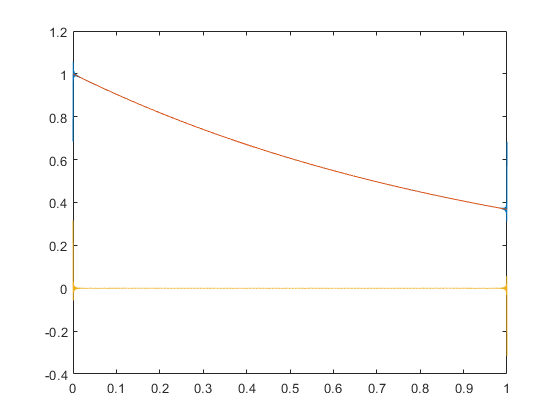

figure(3)
plot(tempoN,pn,tempoN,g(tempoN),tempoN,rn)